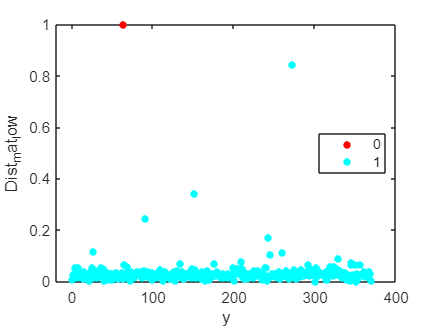

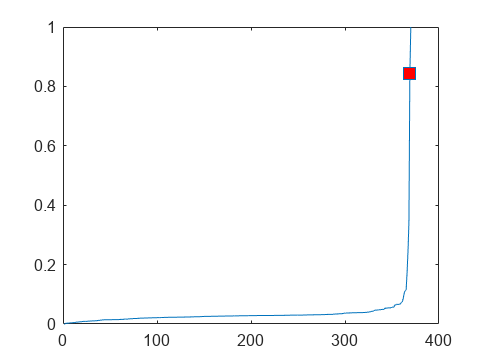

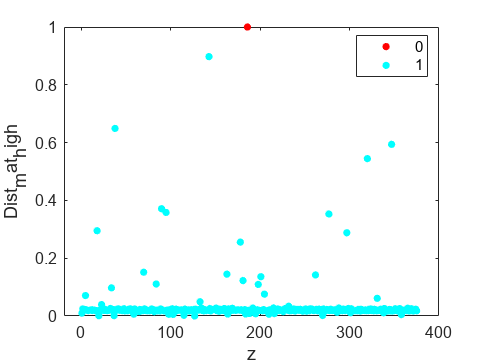

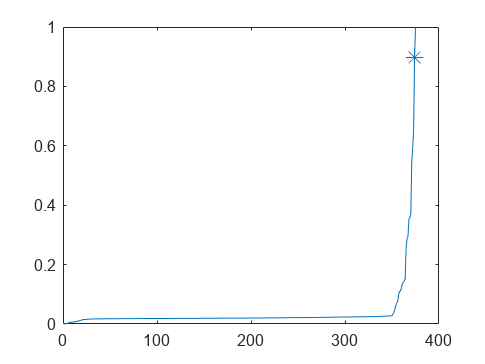

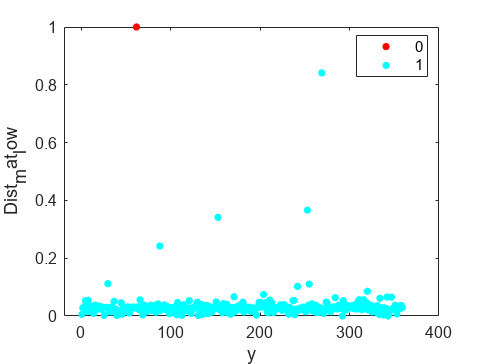

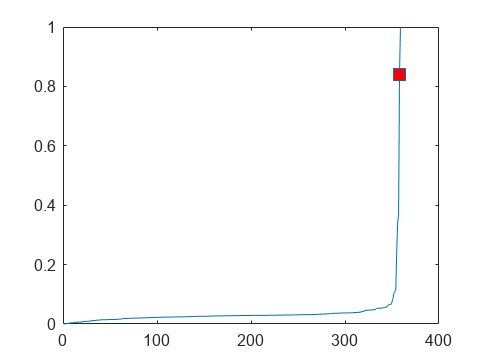

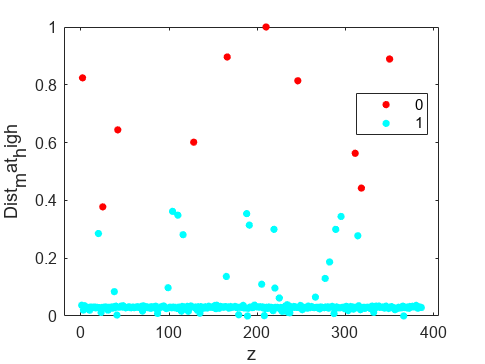

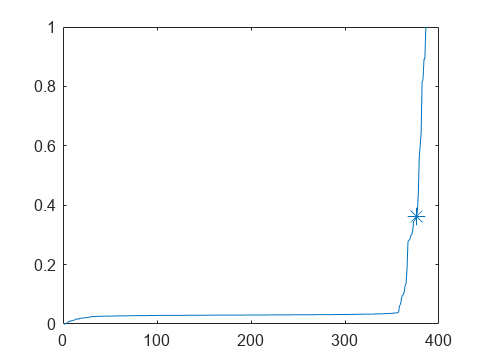

for j = [1,2,3,4,5,6,7,8,9,10]
    figure
    splitfolder=strcat('split',num2str(j));
    per =0;%[50,40,30,20,10,5,2,0];
    for percent = per
        cd C:\Users\shukl\Documents\GitHub\Daily_Weather\
        cd (splitfolder)

        folder=strcat('per',num2str(percent));
        cd (folder)
        my_file = strcat('weather_train_misclass_per_',num2str(percent),'.csv');
        File=readmatrix(my_file,"NumHeaderLines",1);

        low=File(File(:,10)==1,1:9);
        T_low=low.';

        high=File(File(:,10)==2,1:9);
        T_high=high.';

        folder_l1=strcat('ACE_dist_knee_l1pca_per',num2str(percent));
        mkdir (folder_l1)

        numlow=length(T_low);
        T_low_temp=T_low;


        i = 1;
        cd C:\Users\shukl\Documents\GitHub\Daily_Weather

        Dist_mat_low=[];
        TF_low=[];


        BF_low=l1pca_BF(T_low,i,1,10,10,'');
        for k = 1 : numlow

            A=T_low(:,k);
            Dist_mat_low(k)=norm((A-(BF_low*BF_low.'*A)),1);
            k;

        end
        Dist_mat_low;
        min_val=min(Dist_mat_low,[],"all");
        max_val=max(Dist_mat_low,[],"all");
        Dist_mat_low= Dist_mat_low -min_val;%]/[max_val-min_val]
        Dist_mat_low=Dist_mat_low /(max_val-min_val);
        
        Dist_mat_low;

        [Dist_mat_low_asc,Indx_l]=sort(Dist_mat_low,"ascend");

        y_l=Dist_mat_low_asc;
        
        [elbow_l,elbow_indx_l]=knee_pt(y_l);

        
        threshold_dist_l= Dist_mat_low_asc((elbow_indx_l));
     
        ind_O_l=find(Dist_mat_low>threshold_dist_l);
        ind_I_l=find(Dist_mat_low<=threshold_dist_l);

        

        cluster_l=zeros(size(Dist_mat_low));
        cluster_l(ind_I_l)=1;

        figure
        y= 1:1:length(low);
        numGroups = length(unique(cluster_l));
        gscatter(y,Dist_mat_low,cluster_l,hsv(numGroups))
        
        figure
        plot(Dist_mat_low_asc,'-s',"MarkerIndices",(elbow_indx_l),'MarkerFaceColor','red','MarkerSize',10 )


        ind_O_l;
  

        
        T_low_temp(:,ind_O_l)=[];
        Final_low=T_low_temp';
        Final_low(:,10)=1;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        numhigh=length(T_high);
        T_high_temp=T_high;


        i = 1;
        cd C:\Users\shukl\Documents\GitHub\CancerAceFiltering

        Dist_mat_high=[];
        TF_high=[];


        BF_high=l1pca_BF(T_high,i,1,10,10,'');
        for k = 1 : numhigh
            A=T_high(:,k);
            Dist_mat_high(k)=norm((A-(BF_high*BF_high.'*A)),1);
            k;

        end
        Dist_mat_high;
        min_val=min(Dist_mat_high,[],"all");
        max_val=max(Dist_mat_high,[],"all");
        Dist_mat_high= Dist_mat_high -min_val;%]/[max_val-min_val]
        Dist_mat_high=Dist_mat_high /(max_val-min_val);

        Dist_mat_high;

        [Dist_mat_high_asc,Indx_h]=sort(Dist_mat_high,"ascend");

        y_h=Dist_mat_high_asc;
        
        [elbow_h,elbow_indx_h]=knee_pt(y_h);

     
        threshold_dist_h= Dist_mat_high_asc((elbow_indx_h));
        
    
        ind_O_h=find(Dist_mat_high>threshold_dist_h);
        ind_I_h=find(Dist_mat_high<=threshold_dist_h);



        cluster_h=zeros(size(Dist_mat_high));
        cluster_h(ind_I_h)=1;

        figure
        z= 1:1:length(high);
        numGroups = length(unique(cluster_h));
        gscatter(z,Dist_mat_high,cluster_h,hsv(numGroups))

        figure
        plot(Dist_mat_high_asc,'-*',"MarkerIndices",(elbow_indx_h),'MarkerFaceColor','red','MarkerSize',10 )

     
        ind_O_h;
    
        T_high_temp(:,ind_O_h)=[];        

        Final_high=T_high_temp';
        Final_high(:,10)=2;

        cd C:\Users\shukl\Documents\GitHub\Daily_Weather\
        cd (splitfolder)
        cd (folder)

        cd (folder_l1)

        L1pca_file=(horzcat(Final_low.',Final_high.')).';

        L1pca_file = array2table(L1pca_file);
        L1pca_file.Properties.VariableNames(1:10)=  ["air_pressure_9am", "air_temp_9am",	"avg_wind_direction_9am", "avg_wind_speed_9am", "max_wind_direction_9am", "max_wind_speed_9am", "rain_accumulation_9am", "rain_duration_9am","relative_humidity_9am", "relative_humidity_3pm"];
        filel1pca=strcat('weather_misclass_per',num2str(percent),'_ACE_l1pca_',num2str(i),'.csv');
        writetable(L1pca_file,filel1pca);
    end
end